## Example #1

### 2D random point cloud

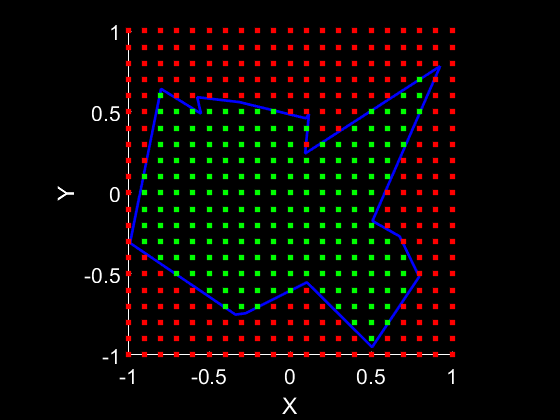

N = 16;
V = 2*(rand(N,2)-0.5);
G = mean(V,1);
V = V - G;
theta = atan2(V(:,2),V(:,1));
[~,i] = sort(theta);
V = V(i,:);
[A B] = meshgrid(-1:0.1:1);
P = cat(2,A(:),B(:));

figure
line([V(:,1); V(1,1)],[V(:,2); V(1,2)],'Color',[0 0 1],'LineWidth',2), hold on;
set(gcf,'Color',[0 0 0]), set(gca,'Color',[0 0 0],'XColor',[1 1 1],'YColor',[1 1 1],'FontSize',16);
xlabel('X'), ylabel('Y');

isin = cell2mat(cellfun(@(c) isinside2Dset(V,c),num2cell(P,2),'un',0));
ColorSpec = cell2mat(cellfun(@(c) cat(2,~c,c,0),num2cell(isin,2),'un',0));

cellfun(@(r1,r2) plot(r1(1,1),r1(1,2),'+','Color',r2,'MarkerSize',4,'LineWidth',4),num2cell(P,2),num2cell(ColorSpec,2),'un',0);
axis equal, axis tight;